# Salt and Pepper Noise Image Denoising Using Deep Learning

This example shows how to train a denoising convolutional neural network (DnCNN), then use the network to reduce Salt & Pepper noise in an image.Finally it will compare the results with other denoising approaches.

Some of the functions used in this livescript require the Deep Learning Toolbox™. If this support package is not installed, the functions provide the download links.

If you choose to train the DnCNN network, use of a CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended (requires Parallel Computing Toolbox™). 

% Clear workspace and command window
clear;
clc;

## Introduction

Salt and Pepper noise is a type of impulsive noise sometimes seen on images. This noise can be caused by sharp and sudden disturbances in the image signal. It presents itself as sparsely occurring white and black pixels. The percentage of pixles that present this behavior is also called as *density* of the salt and pepper noise. 

Let’s load first a grayscale image. Then create a noisy version of it by adding Salt and Pepper noise using the function [imnoise](https://www.mathworks.com/help/images/ref/imnoise.html).  An effective noise reduction method for this type of noise is a median filter, while mean/Gaussian filter usually is not effective. The function [`medfilt2`](https://www.mathworks.com/help/images/ref/medfilt2.html) will apply the median filter, while [`imgaussfilt`](https://www.mathworks.com/help/images/ref/imgaussfilt.html) will apply the Gaussian filter.

We use the [`imcrop`](https://www.mathworks.com/help/images/ref/imcrop.html) function to display a crop of the image and visualize it.

I = rgb2gray( imread('lighthouse.png') ); % Read the image

density = 0.05;
I_noisy = imnoise(I,'salt & pepper',density); % Add salt and pepper noise to the image of a given density

denoisedI_med  = medfilt2(I,[5,5],'symmetric'); % Apply the median filter on 5x5 windows
denoisedI_mean = imgaussfilt(I_noisy,0.4,'FilterSize',15,'FilterDomain','spatial'); % Apply the Gaussian filter 

% Show the original image, its noisy version and the denoised version using
% a Median or a Gaussian filter 
figure();
subplot(1,2,1); imshow(I);              title('Pristine');
subplot(2,2,2); imshow(I_noisy);        title('Salt and pepper');
subplot(2,2,3); imshow(denoisedI_med);  title('Median filter');
subplot(2,2,4); imshow(denoisedI_mean); title('Gaussian filter');

This example uses a built-in deep feed-forward convolutional neural network, called `DnCNN`. The network was primarily designed to remove Gaussian noise from images. However, the DnCNN architecture can also be trained to remove Salt and Pepper noise.

The reference paper [1] employs a residual learning strategy, meaning that the DnCNN network learns to estimate the residual image. A residual image is the difference between a pristine image and a distorted copy of the image. The residual image contains information about the image distortion.

## Preparing Data for Training

Download the IAPR TC-12 Benchmark, which consists of 20,000 still natural images [[2](https://it.mathworks.com/help/images/jpeg-image-deblocking-using-deep-learning.html#mw_rtc_JPEGImageDeblockingDeepLearningExample_96359323)]. The data set includes photos of people, animals, cities, and more. The size of the data file is ~1.8 GB. If you do not want to download this training data set, you can use the images available in the Image Toolbox folder by flagging the *small_ds *variable. Finally, we create an [`ImageDatastore`](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) object that stores pristine images.

small_ds = true; % The IAPR TC-12 dataset will take some minutes to download

if small_ds
    exts = {'.jpg','.png'};
    fileNames = {'sherlock.jpg','car2.jpg','fabric.png','greens.jpg','hands1.jpg','kobi.png',...
    'lighthouse.png','micromarket.jpg','office_4.jpg','onion.png','pears.png','yellowlily.jpg',...
    'indiancorn.jpg','flamingos.jpg','sevilla.jpg','llama.jpg','parkavenue.jpg',...
    'peacock.jpg','car1.jpg','strawberries.jpg','wagon.jpg'};
    filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
    filePathNames = strcat(filePath,fileNames);
    imdsPristine_train = imageDatastore(filePathNames(1:end-6),'FileExtensions',exts);
    imdsPristine_val = imageDatastore(filePathNames(end-5:end),'FileExtensions',exts);
else
    imagesDir = fullfile('.');
    url = "http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz";
    downloadIAPRTC12Data(url,imagesDir);
    trainImagesDir = fullfile(imagesDir,'iaprtc12','images','01');
    valImagesDir = fullfile(imagesDir,'iaprtc12','images','00');
    exts = {'.jpg','.bmp','.png'};
    imdsPristine_train = imageDatastore(trainImagesDir,'FileExtensions',exts); 
    imdsPristine_val = imageDatastore(valImagesDir,'FileExtensions',exts);
end

### Creating a Denoising Image Datastore

We use modified version of the [denoisingImageDatastore](https://it.mathworks.com/help/images/ref/denoisingimagedatastore.html) object to generate batches of noisy image patches and corresponding noise patches from images in the `ImageDatastore `created. The patches are used to train a denoising deep neural network.

The denoising image datastore creates many patches from each image in the image datastore and adds salt and pepper noise to the patches of a given density.

patchSize = 50;
patchesPerImage = 128;
densityNoiseLevel = 0.05;

dnds_train = denoisingImageDatastore_SaltPepper(imdsPristine_train,...
    'PatchesPerImage',patchesPerImage,...
    'PatchSize',patchSize,...
    'DensityNoiseLevel',densityNoiseLevel,...
    'ChannelFormat', 'gray')

dnds_val = denoisingImageDatastore_SaltPepper(imdsPristine_train,...
    'PatchesPerImage',patchesPerImage,...
    'PatchSize',patchSize,...
    'DensityNoiseLevel',densityNoiseLevel,...
    'ChannelFormat', 'gray')

### Visualizing training patch

To visualize the data in a denoising image datastore, we can use the [`preview`](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.preview.html) function, which returns a subset of data in a table. The `input` variable contains the noisy image patches and the `response` variable contains the corresponding noise patches. Visualize all of the noisy image patches or noise patches in the same figure by using the [`montage`](https://it.mathworks.com/help/images/ref/montage.html) function. 

Each time images are read from the denoising image datastore, salt and pepper noise is added to each image.

minibatch = preview(dnds_train);
montage(minibatch.input)
figure;
montage(minibatch.response)

### **Defining DnCNN architecture**

In this example, we use the pre-trained DnCNN architecture and weights (transfer learning).

There are different ways to create a neural network in MATLAB, here we will do it programmatically using [denoisingNetwork](https://www.mathworks.com/help/images/ref/denoisingnetwork.html) function.

SaltPepperDnCnn_net = denoisingNetwork('DnCNN');

## **Train DnCNN network with Deep Network Designer**

The Deep Network Designer (DND) provides a graphical interface for designing a neural network. If you are working with images, you can upload your data and train the network within the DND. For sequence data this feature will come in the near future.

To open the DND app go to the **Apps** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html).

### Import the network from the workspace

On opening the DND, choose to load the network `From workspace` and select the `SaltPepperDnCnn_net`.

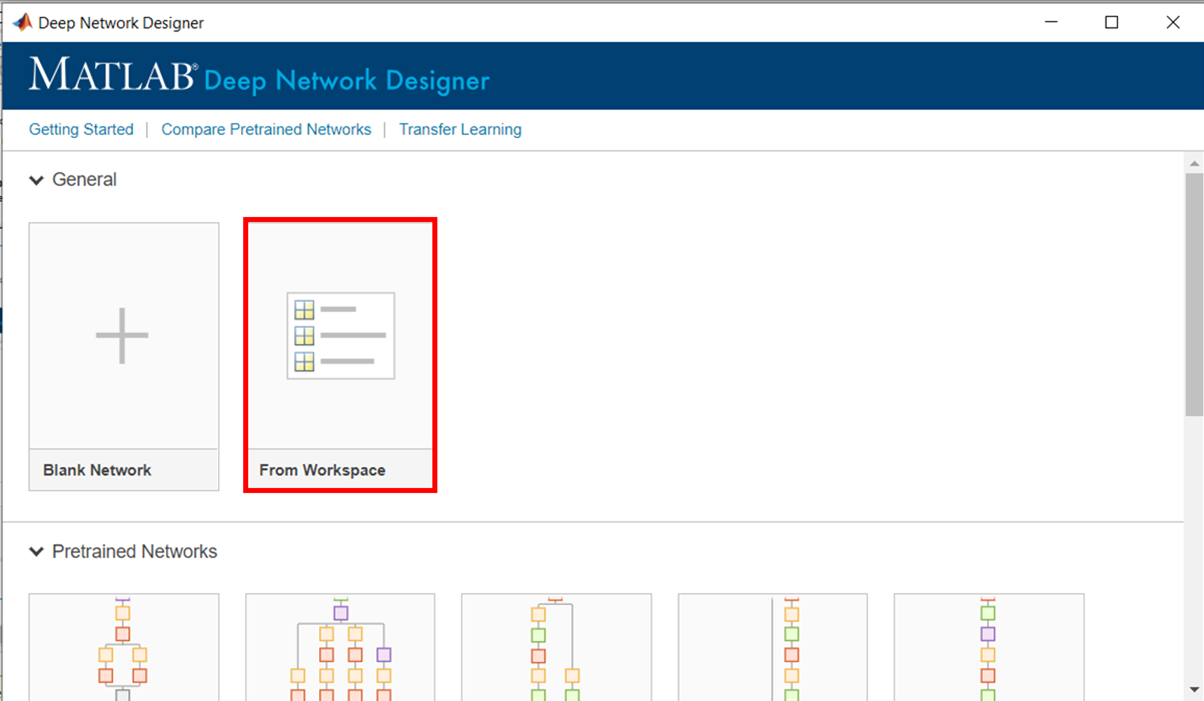

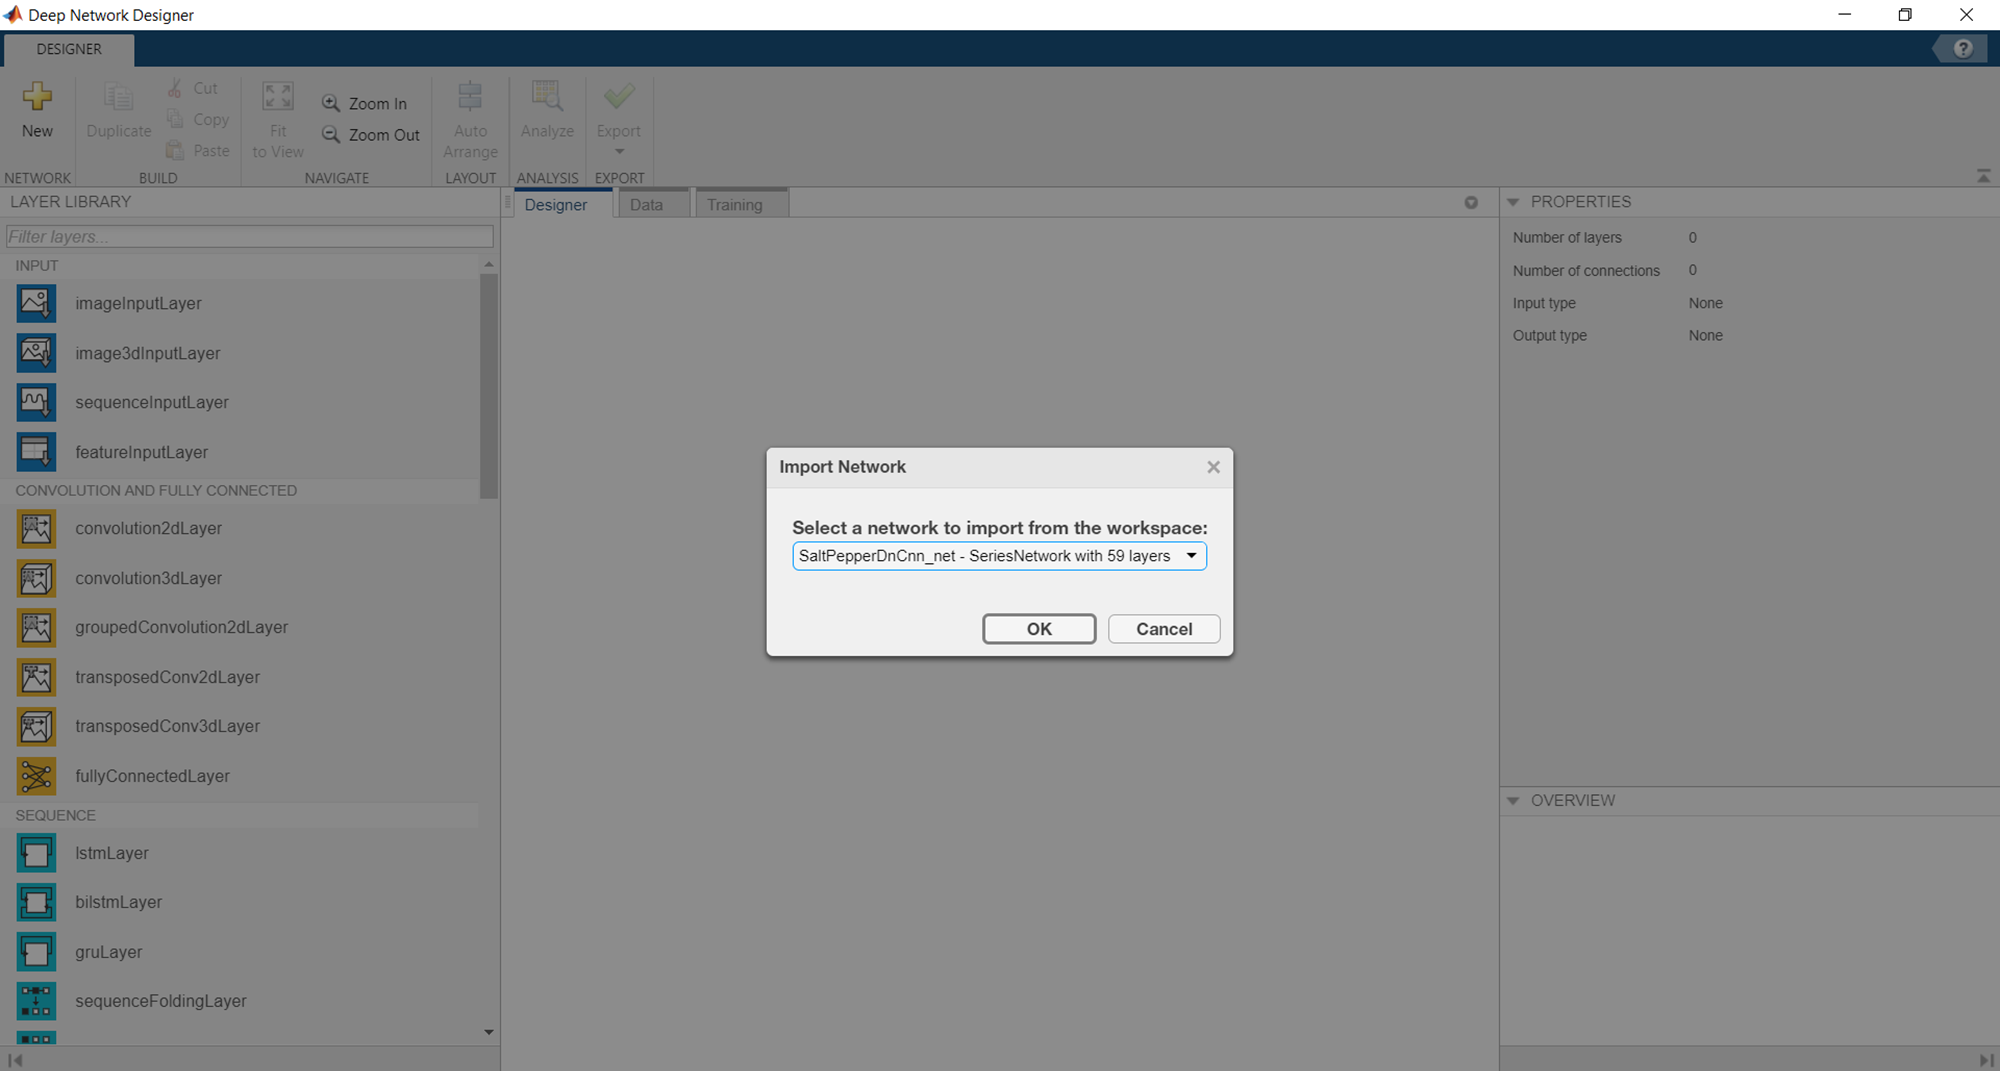

### Import the Datastore form the workspace

Form the `Data `tab, import the `denoisingImageDatastore_SaltPepper `datastores for the training and validation phase`.`

 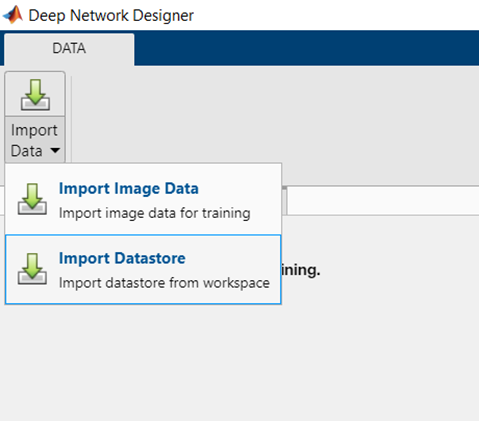

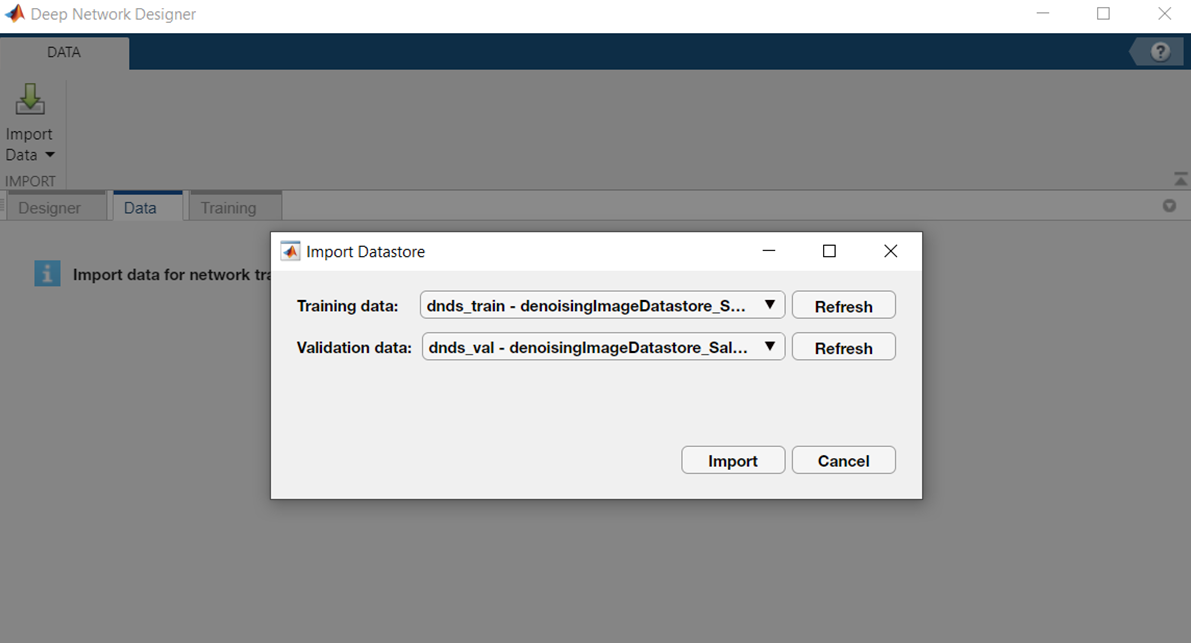

### Setting Training Options

Form the `Training `tab, set the training options as the following:

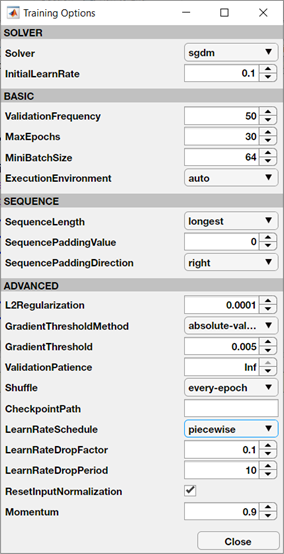

### Train the network

Note that the training will take approximately 20 mins on a GPU. To avoid waiting **do NOT** train the network in the DND and proceed with the next section, where a pre-trained network can be loaded.

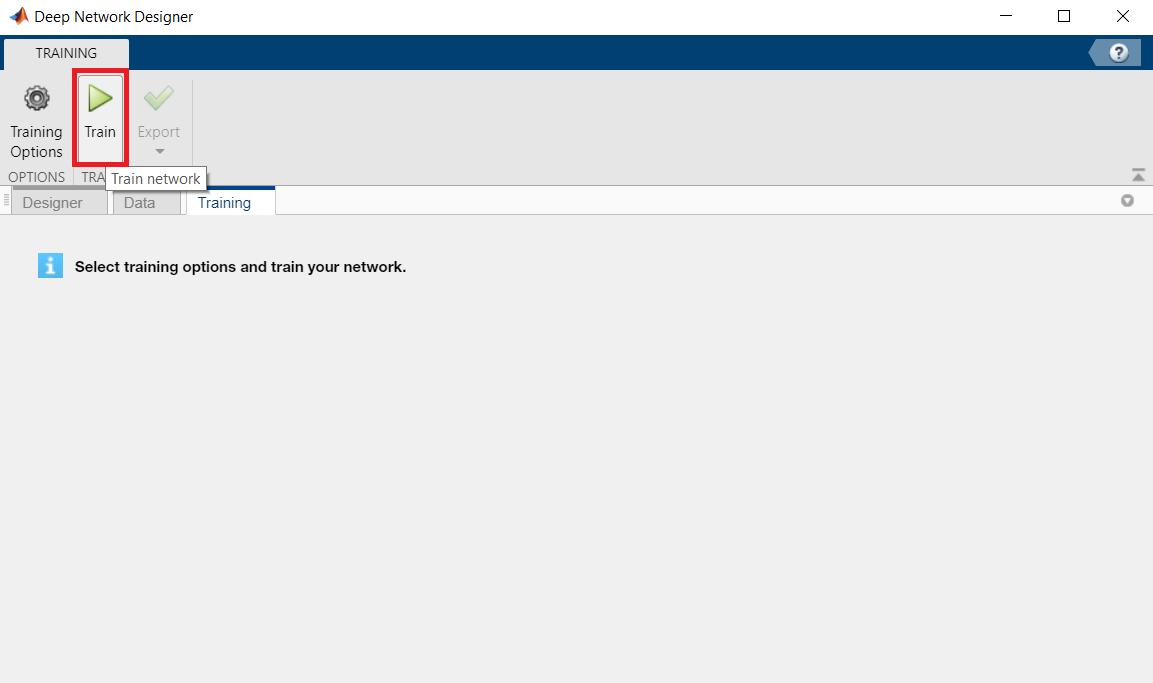

If you train the network the training plot should look similar to this:

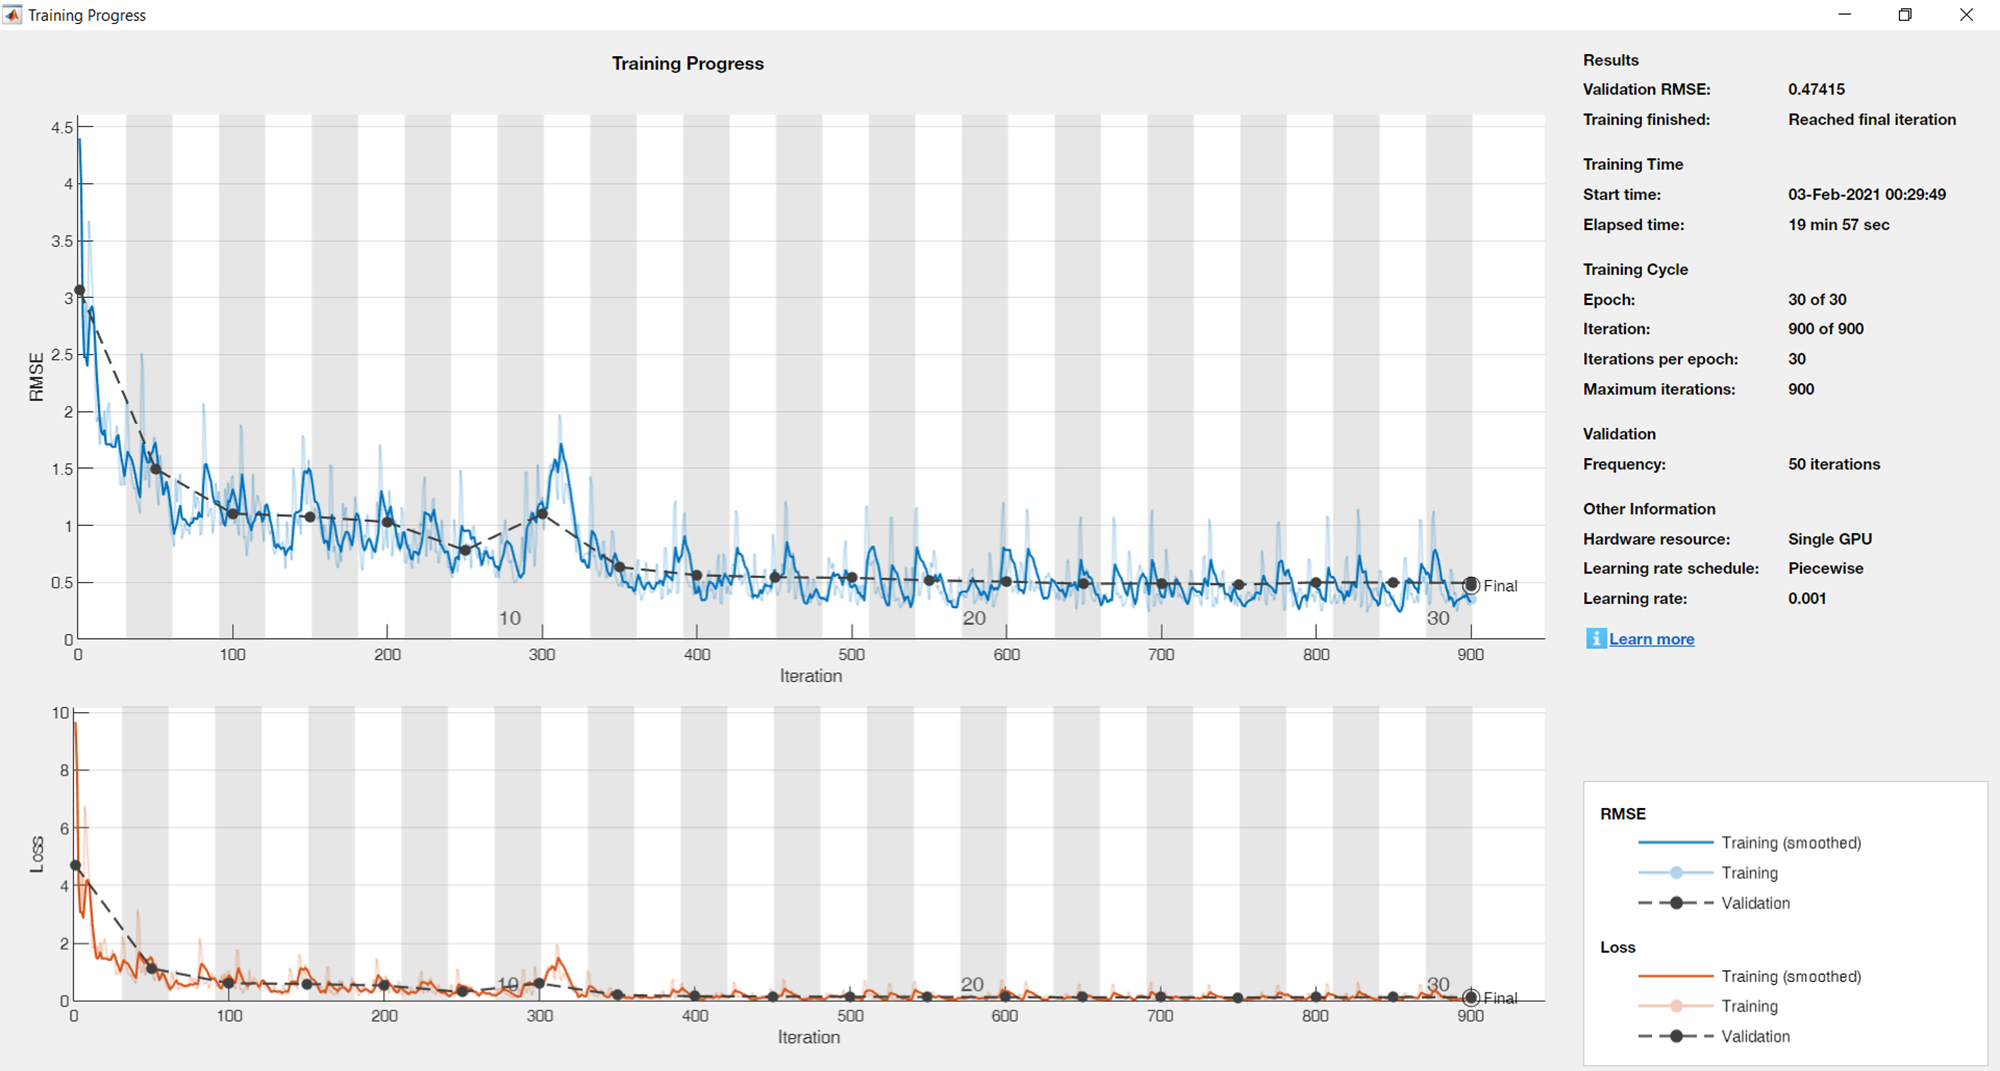

## **Train DnCNN network programatically**

The same process could be done programmatically.

### Setting Training Options

Set the training options as the following:

maxEpochs = 30;
initLearningRate = 0.1;
l2reg = 0.0001;
batchSize = 64;

options = trainingOptions('sgdm', ...
    'Momentum',0.9, ...
    'InitialLearnRate',initLearningRate, ...
    'LearnRateSchedule','piecewise', ...
    'GradientThresholdMethod','absolute-value', ...
    'GradientThreshold',0.005, ...
    'L2Regularization',l2reg, ...
    'MiniBatchSize',batchSize, ...
    'MaxEpochs',maxEpochs, ...
    'Shuffle','every-epoch',...
    'ValidationData', dnds_val,...
    'Plots','training-progress',...
    'Verbose',false);

### Training the Network

Note that the training will take approximately 20 mins on a GPU. To avoid waiting choose `doTrain = false` to load a pre-trained network.

doTrain = false;
if doTrain
    [SaltPepperDnCnn_net,info] = trainNetwork(dnds_train,SaltPepperDnCnn_net.Layers,options);
    save(['trainedSaltPepperDnCnn.mat'],'SaltPepperDnCnn_net','options');    
else
    load(['pretrainedSaltPepperDnCnn.mat']);
end

## Apply the DnCNN Network

Let's test our `SaltPepperDnCnn` network. Please note that the following code is executed on the test data, namely the portion of the data that has never been used so far. Thus, the results are fair and can provide a reliable estimate of how the denoising network will behave in a real world scenario.

#### Generate a noisy image

testDir = fullfile('.', 'TestImages'); 
exts = {'.jpg','.bmp','.png'};
imds_test = imageDatastore(testDir,'FileExtensions',exts); 

indx = 1; % Index of image to read from the test image datastore
IRGB = readimage(imds_test,indx);

% Read the image
I = rgb2gray(IRGB);
I = im2double(I);

noise_density  = 0.05; % Density of salt and pepper noise
I_noisy = imnoise(I,'salt & pepper',noise_density); % Add noise

%Show the clean image and its noisy version
figure();
imshow(I);
title('Original Image'); 
imshow(I_noisy);
title('Noisy RGB Image');

% Calculate the PSNR and the SSIM of the noisy image
noisyPSNR = psnr(I_noisy,I);
fprintf('\n The PSNR value of the noisy image is %0.4f.',noisyPSNR);
noisySSIM = ssim(I_noisy,I);
fprintf('\n The SSIM value of the noisy image is %0.4f.',noisySSIM);

#### Denoise with the SaltPepperDnCNN network

I_denoised_SP_CNN = denoiseImage(I_noisy,SaltPepperDnCnn_net);
imshow(I_denoised_SP_CNN);
title('Denoised Image with DnCNN for Gaussian Noise');

% Calculate the PSNR and the SSIM of the denoised image (with SaltPepperDnCnn_net)
denoisedPSNR_SP_CNN = psnr(I_denoised_SP_CNN,I);
fprintf('\n The PSNR value of the denoised image is %0.4f, with a gain of %0.4f.',denoisedPSNR_SP_CNN,denoisedPSNR_SP_CNN-noisyPSNR);
denoisedSSIM_SP_CNN = ssim(I_denoised_SP_CNN,I);
fprintf('\n The SSIM value of the noisy image is %0.4f.',denoisedSSIM_SP_CNN);

## Comparison

Let's compare our `SaltPepperDnCnn` network with the DnCNN trained for Gaussian Noise and with the classical median filter.

#### Compare with the DnCNN network for Gaussian Noise

We compare the results of denoising with the DnCNN pretrained for Gaussian Noise removal.

% reconstruct the image
DnCNN_net = denoisingNetwork('DnCNN'); 
I_denoised_CNN = denoiseImage(I_noisy,DnCNN_net);

% show the results
imshow(I_denoised_CNN);
title('Denoised Image with built-in DnCNN');

% Calculate the PSNR and the SSIM of the denoised image (with DnCnn_net)
denoisedPSNR_CNN = psnr(I_denoised_CNN,I);
fprintf('\n The PSNR value of the denoised image is %0.4f, with a gain of %0.4f.',denoisedPSNR_CNN,denoisedPSNR_CNN-noisyPSNR);
denoisedSSIM_CNN = ssim(I_denoised_CNN,I);
fprintf('\n The SSIM value of the denoised image is %0.4f. with a gain of %0.4f',denoisedSSIM_CNN, denoisedSSIM_CNN-noisySSIM);

#### Compare with the median filter

We also compare the results with the median filter.

% reconstruct the image
I_denoised_mf = medfilt2(I_noisy,[5 5],'symmetric');

% show the results
imshow(I_denoised_mf);
title('Denoised Image with Median Filter');

% Calculate the PSNR and the SSIM of the denoised image (with median filter)
denoisedPSNR_mf = psnr(I_denoised_mf,I);
fprintf('\n The PSNR value of the denoised image is %0.4f, with a gain of %0.4f.',denoisedPSNR_mf,denoisedPSNR_mf-noisyPSNR);
denoisedSSIM_mf = ssim(I_denoised_mf,I);
fprintf('\n The SSIM value of the denoised image is %0.4f. with a gain of %0.4f',denoisedSSIM_mf, denoisedSSIM_mf-noisySSIM);

#### Results of comparison

As you can see the PSNR and the SSIM of the image denoised with our re-trained *SaltPepperDnCnn_net*  filter works better than the median filter and the DnCNN trained for Gaussian noise.

## References

[1] Zhang, K., W. Zuo, Y. Chen, D. Meng, and L. Zhang, "Beyond a Gaussian Denoiser: Residual Learning of Deep CNN for Image Denoising." *IEEE**®* *Transactions on Image Processing*. Feb 2017.

[2] Grubinger, M., P. Clough, H. Müller, and T. Deselaers. "The IAPR TC-12 Benchmark: A New Evaluation Resource for Visual Information Systems." *Proceedings of the OntoImage 2006 Language Resources For Content-Based Image Retrieval*. Genoa, Italy. Vol. 5, May 2006, p. 10.

## Further readings

- [Train and Apply Denoising Neural Networks](https://www.mathworks.com/help/images/train-and-apply-denoising-neural-networks.html)

- [Remove Noise from Color Image Using Pretrained Neural Network](https://it.mathworks.com/help/images/remove-noise-from-color-image-using-pretrained-neural-network.html)

- [JPEG Image Deblocking Using Deep Learning](https://it.mathworks.com/help/images/jpeg-image-deblocking-using-deep-learning.html)